net = feedforwardnet(2,'traingd');
net.inputs{1}.processFcns = {}; % modify the process function for inputs
net.outputs{2}.processFcns = {}; % modify the process function for outputs

net.layers{1}.transferFcn = 'tansig'; % the transfer function for the first layer
%net.layers{2}.transferFcn = 'tansig'; % the transfer function for the second layer
%net.layers{3}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'softmax';

net.performFcn = 'crossentropy'; %the loss function
net.trainParam.epochs = 10000;
net.trainParam.lr = 0.001; % learning rate. You may need to adjust it in the experiment.
%

X = low_dim_data;
Y= groundTruthOneHot_ovo';

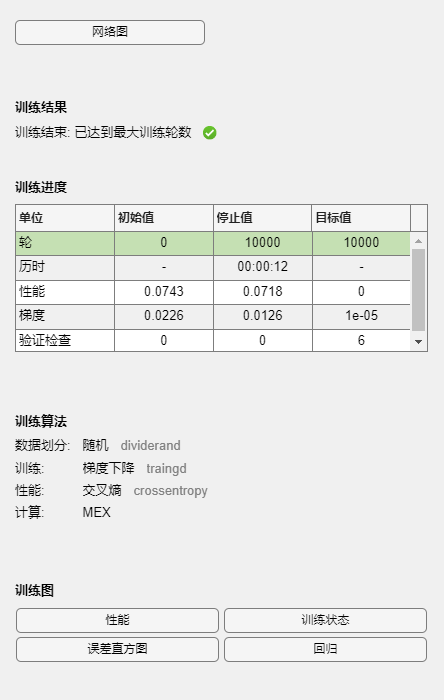


numClasses = 2;
% 交叉验证配置
K = 5; % 10折交叉验证
cv = cvpartition(size(X, 1), 'KFold', K);

% 初始化性能追踪变量
accuracies = zeros(K, 1);
AUCs = zeros(numClasses, K); % 假设有多个类别

% 交叉验证循环
for k = 1:K
    % 划分训练集和测试集
    idx = cv.test(k);
    XTrain = X(~idx, :)';
    YTrain = Y(~idx, :)';
    XTest = X(idx, :)';
    YTest = Y(idx, :)';

    % 训练网络
    net = train(net, XTrain, YTrain);

    % 测试网络
    predictions = sim(net, XTest);

    % 计算预测的准确率
    numColumns = size(predictions, 2);

    % 初始化一个行索引向量
    maxRowIndices = zeros(1, numColumns);

    % 对于矩阵的每一列
    for columnIndex = 1:numColumns
        % 找到该列的最大元素所在的行索引
        maxElement = max(predictions(:, columnIndex));
        maxRowIndices(columnIndex) = find(predictions(:, columnIndex) == maxElement);
    end

    accuracy_morelayer = sum(maxRowIndices== vec2ind(YTest)) / length(YTest)*100;

   
end

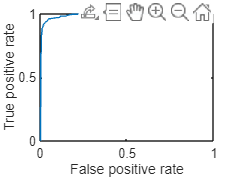

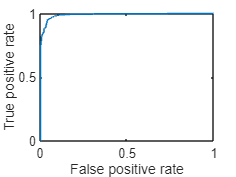

 % 计算每个类别的AUC
numClasses = size(YTest, 1); % 假设 YTest 是一个 one-hot 编码的矩阵
for i = 1:numClasses
    % 提取第 i 个类别的标签
    actual = YTest(i, :);
    
    % 提取对应的预测得分
    scores = predictions(i, :);

    % 计算性能曲线
    [X, Y, ~, AUC] = perfcurve(actual, scores, 1);

    % 绘制ROC曲线
    figure;
    plot(X, Y)
    xlabel('False positive rate') 
    ylabel('True positive rate')
   
end


% 计算平均准确率和AUC
meanAccuracy = mean( accuracy_morelayer);
% 显示结果

disp(['Average Accuracy: ', num2str(meanAccuracy)]);

Average Accuracy: 95.1111
